clc,clear,close all

global U
global num
global Num
global Umod
global hstep
global M2
global Upm
global Center
global Element
global M
global m_Hflux
global Umod

设置方程

u0 = @(x) sin(-pi*x);
left = -1;
right = 1;
time = 0.5/pi;
num = 80;  % 区间数量
M2 = 9;

分配内存

Num = num+2;    % 周期边界条件，左右各加一个区间后，区间数量

delta_t = 0.1*(right-left)/num;

hstep = (right-left)/num;   % 每个区间的长度，这里设置成等长。
Element_l = left-hstep:hstep:right; % 每个区间的左边界，大小为 1xNum
Element_r = left:hstep:right+hstep; % 每个区间的右边界，大小为 1xNum
Element = [Element_l',Element_r'];  % 每个区间的左右边界，大小为 Numx2
Center = mean(Element,2);           % 每个区间的中心点，大小为 Numx1

U = zeros(Num,3);       % 每个区间上的三个自由度
Umod = zeros(Num,2);
Upm = zeros(Num,2);

U0 = zeros(Num,3);
U1 = zeros(Num,3);
U2 = zeros(Num,3);
Un = zeros(Num,3);


m_Hflux = zeros(Num,1);   % num 个区间中间的 num+1 个间隔点上的数值通量。其中第一个位置只储存0。
M  = zeros(1,Num);

basefun0 = @(i,x) 1;
basefun1 = @(i,x) x-Center(i);
basefun2 = @(i,x) (x-Center(i)).^2-1/12*hstep^2;

a0 = 1;
a1 = 12.0 / hstep;
a2 = 180.0 / hstep^2;
u_fun = @(i,x) a0 * U(i,1) + a1 * U(i,2) * basefun1(i,x) + a2 * U(i,3) * basefun2(i,x);

## MainSolver

### 初始化

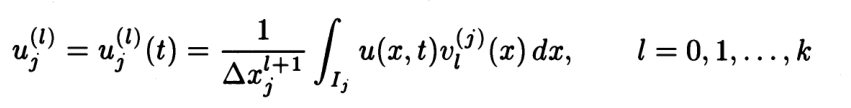

for i = 2:num+1

    a_i = Element(i,1);
    b_i = Element(i,2);

    int1 = quadgk(@(x)u0(x)*basefun0(i,x),a_i,b_i);
    U(i,1) = int1 / hstep;

    int2 = quadgk(@(x)u0(x).*basefun1(i,x),a_i,b_i);
    U(i,2) = int2 / hstep^2;

    int3 = quadgk(@(x)u0(x).*basefun2(i,x),a_i,b_i);
    U(i,3) = int3 / hstep^3;
end

龙格库塔迭代

now = 0;
while now<time
    if now+delta_t>time
        delta_t = time-now;
    end
    RungeKutta2(delta_t);
    now = now+delta_t;
    now
end

now = 0.0025

now = 0.0050

now = 0.0075

now = 0.0100

now = 0.0125

now = 0.0150

now = 0.0175

now = 0.0200

now = 0.0225

now = 0.0250

now = 0.0275

now = 0.0300

now = 0.0325

now = 0.0350

now = 0.0375

now = 0.0400

now = 0.0425

now = 0.0450

now = 0.0475

now = 0.0500

now = 0.0525

now = 0.0550

now = 0.0575

now = 0.0600

now = 0.0625

now = 0.0650

now = 0.0675

now = 0.0700

now = 0.0725

now = 0.0750

now = 0.0775

now = 0.0800

now = 0.0825

now = 0.0850

now = 0.0875

now = 0.0900

now = 0.0925

now = 0.0950

now = 0.0975

now = 0.1000

now = 0.1025

now = 0.1050

now = 0.1075

now = 0.1100

now = 0.1125

now = 0.1150

now = 0.1175

now = 0.1200

now = 0.1225

now = 0.1250

now = 0.1275

now = 0.1300

now = 0.1325

now = 0.1350

now = 0.1375

now = 0.1400

now = 0.1425

now = 0.1450

now = 0.1475

now = 0.1500

now = 0.1525

now = 0.1550

now = 0.1575

now = 0.1592

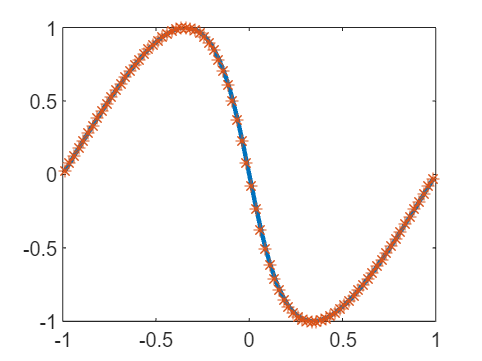

for i = 2:num+1
    x(i-1) = Center(i);
    y(i-1) = u(i,Center(i));
end
xx = x;
syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u0(xi)*time);
    yy(i) = double(u0(xii));
end

err1 = abs(y-yy);
plot(xx,y,'LineWidth',2)
hold on
plot(xx,yy,'*')

num

num = 80

disp(norm(err1,inf))

   1.4761e-05

